**Physics 3605W Homework 2 (Workshop)**

1) Measurements of the frequency of a very slow optical pulsar

data = dlmread('PHYS 3605W/Homework/pulsarData.csv',',',1,0)

data =     1.5300    0.0800
    1.6900    0.2500
    1.5000    0.9000
    1.4100    0.1400
    1.6200    0.1300
    1.9400    0.5800
    1.6100    0.1100
    1.2900    0.3200


freq = data(:,1)

freq =     1.5300
    1.6900
    1.5000
    1.4100
    1.6200
    1.9400
    1.6100
    1.2900


freqErr = data(:,2)

freqErr =     0.0800
    0.2500
    0.9000
    0.1400
    0.1300
    0.5800
    0.1100
    0.3200


a. Histogram of values, histogram of uncertainties

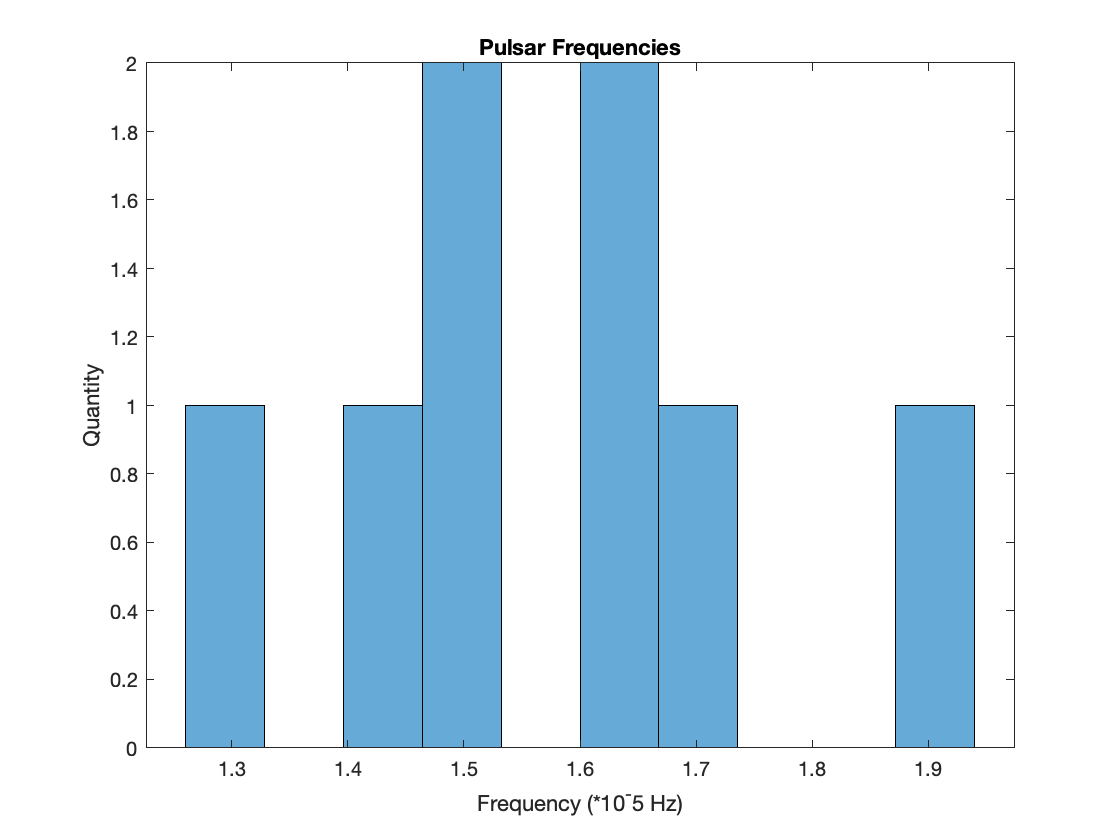

histogram(freq, 10)
title('Pulsar Frequencies')
xlabel('Frequency (*10^-5 Hz)')
ylabel('Quantity')

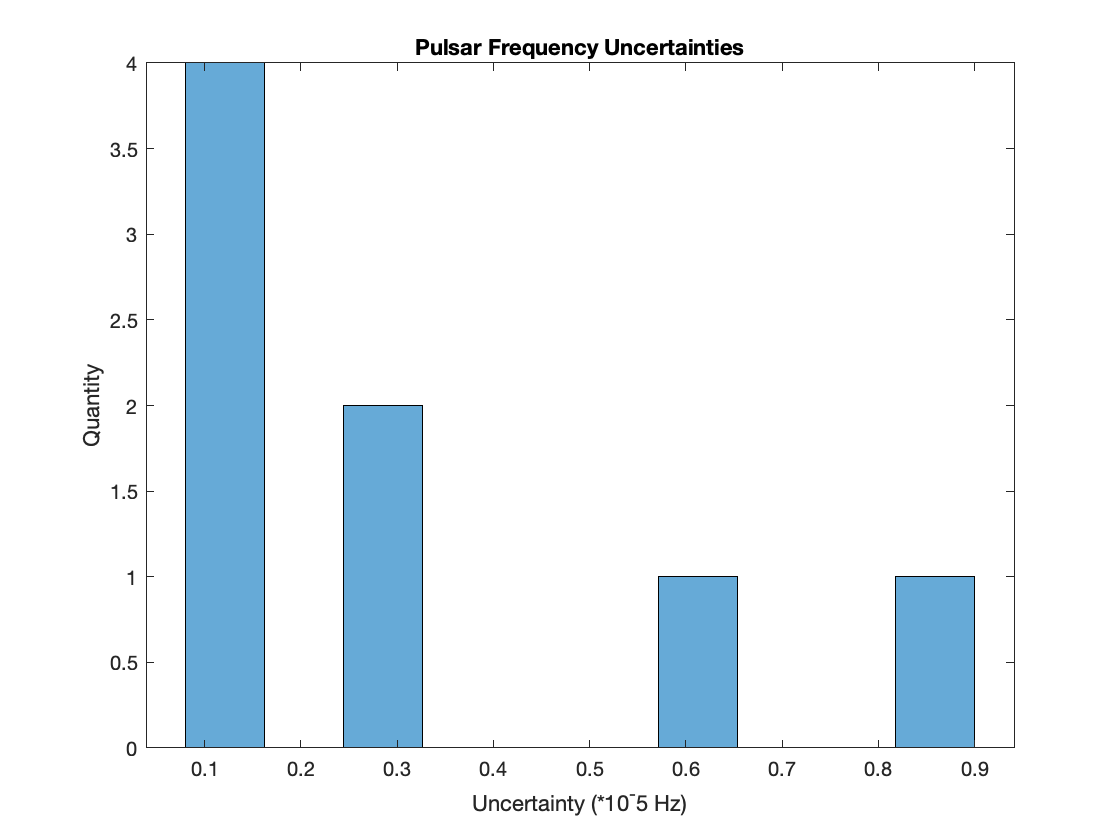


histogram(freqErr, 10)
title('Pulsar Frequency Uncertainties')
xlabel('Uncertainty (*10^-5 Hz)')
ylabel('Quantity')

b. Estimation of true frequency and uncertainty

sum1 = sum(freq ./ freqErr.^2)

sum1 = 587.1736

sum2 = sum(1 ./ freqErr.^2)

sum2 = 379.0595

weightedMeanFreq = sum1/sum2

weightedMeanFreq = 1.5490


weightedFreqErr = sqrt(1/sum(1 ./ freqErr.^2))

weightedFreqErr = 0.0514


meanFreq = sum(freq)/8

meanFreq = 1.5738

meanErr = sqrt(sum(freqErr.^2)/8)

meanErr = 0.4133

So the estimated true value of frequency is (1.55 +/- 0.051 ) * 10^5 Hz

The straight mean and uncertainty for the frequency is (1.57 +/- 0.41) * 10^5 Hz. We can see that the straight value of uncertainty is    larger than the weighted value, since it weighs all values of uncertainty equally. 

c. Chi and chi-squared value for each data point

chi = (freq - weightedMeanFreq)./freqErr

chi =    -0.2378
    0.5639
   -0.0545
   -0.9931
    0.5459
    0.6741
    0.5543
   -0.8095


chiSquared = chi.^2

chiSquared =     0.0566
    0.3180
    0.0030
    0.9862
    0.2981
    0.4544
    0.3072
    0.6552


d. Histogram of chi values of each data point

histogram(chi, 10)
title("Chi values of each data point")
xlabel("Chi values")
ylabel("Quantity")

2) Measurement of resonent frequencies of acoustic modes

a. Plot of data with error bars

n = [1;2;3;4;5;6]

n =      1
     2
     3
     4
     5
     6


f = [314;557;870;1134;1289;1674]

f =          314
         557
         870
        1134
        1289
        1674


s_f = [35;42;51;62;74;86]

s_f =     35
    42
    51
    62
    74
    86


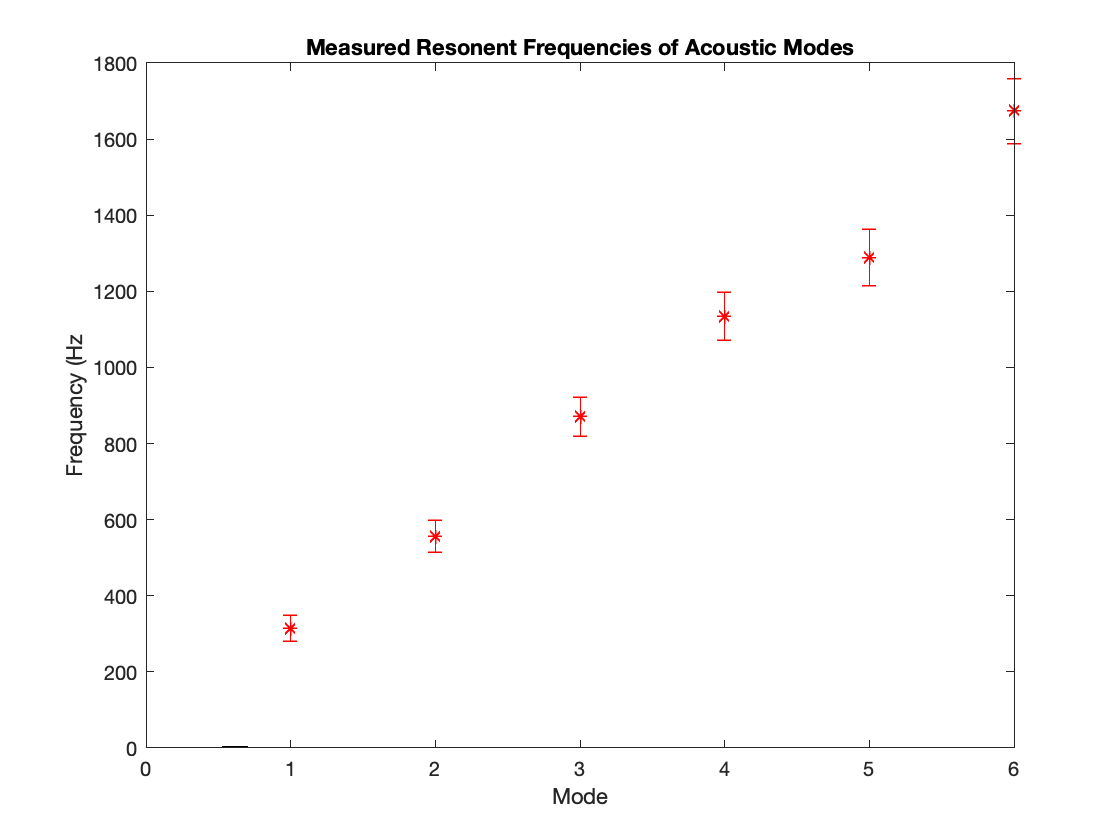


hold on

errorbar(n,f,s_f,'r*','LineStyle','none')

title('Measured Resonent Frequencies of Acoustic Modes')
xlabel('Mode')
ylabel('Frequency (Hz')
xlim([0 6])

hold off

b. Linear fit (format y = a +bx)

scatter(n,f)
title('Measured Resonent Frequencies of Acoustic Modes')
xlabel('Mode')
ylabel('Frequency (Hz')
hl = lsline

hl =   Line (lsline) with properties:

              Color: [0.7500 0.7500 0.7500]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 6]
              YData: [311.5714 1.6344e+03]
              ZData: [1×0 double]

  Show all properties


var = [ones(size(hl.XData(:))), hl.XData(:)]\hl.YData(:);
b = var(2)

b = 264.5714

a = var(1)

a = 47.0000

fo = a

fo = 47.0000

L = 0.45

L = 0.4500

v = 2*L*b

v = 238.1143

v = 238 m/s , fo = 47 Hz

Getting uncertainty on v and fo

s = sum(1./s_f.^2)

s = 0.0023

s_y = sum(f./s_f.^2)

s_y = 1.6633

s_x = sum(n./s_f.^2)

s_x = 0.0059

s_xx = sum((n.^2)./s_f.^2)

s_xx = 0.0201


del = s*s_xx - s_x^2

del = 1.2802e-05


s_b = s/del

s_b = 183.2328

s_a = s_xx/del

s_a = 1.5732e+03


s_v = sqrt(2*L*s_b)

s_v = 12.8417

s_fo = sqrt(s_a)

s_fo = 39.6636

$\sigma_V =13$ m/s and $\sigma_{\mathrm{Fo}} =40\ldotp$ Hz		

c. Predicted frequency for each mode

f_pred = (v.*n)/(2*L) + fo

f_pred = 	1.0e+03 *

    0.3116
    0.5761
    0.8407
    1.1053
    1.3699
    1.6344



hold on

errorbar(n,f,s_f,'r*','LineStyle','none')

title('Measured Resonent Frequencies of Acoustic Modes')
xlabel('Mode')
ylabel('Frequency (Hz')
xlim([0 6])

sz = 60

sz = 60

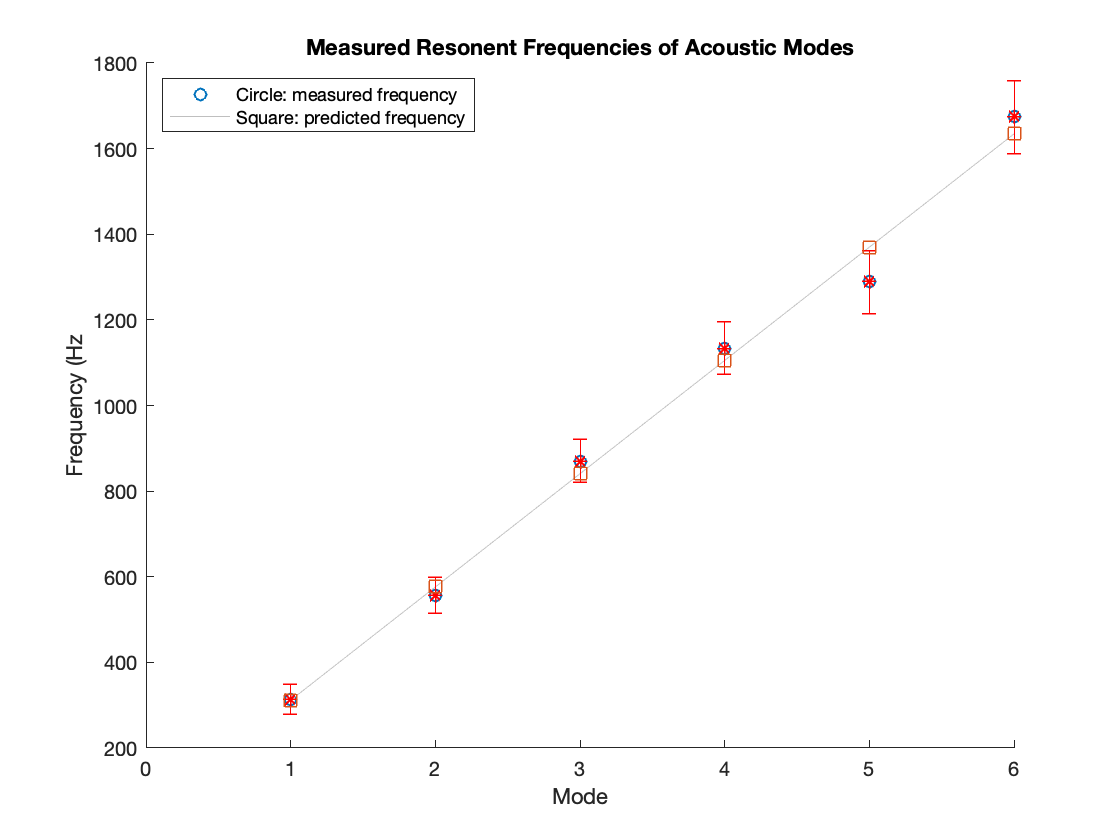

scatter(n,f_pred, sz, 's')
legend({'Circle: measured frequency','Square: predicted frequency'},'Location','northwest')

hold off

d. Chi-values

weightedMean_f = s_y/s

weightedMean_f = 709.1011

chi = (f - f_pred)./s_f

chi =     0.0694
   -0.4558
    0.5742
    0.4631
   -1.0927
    0.4601


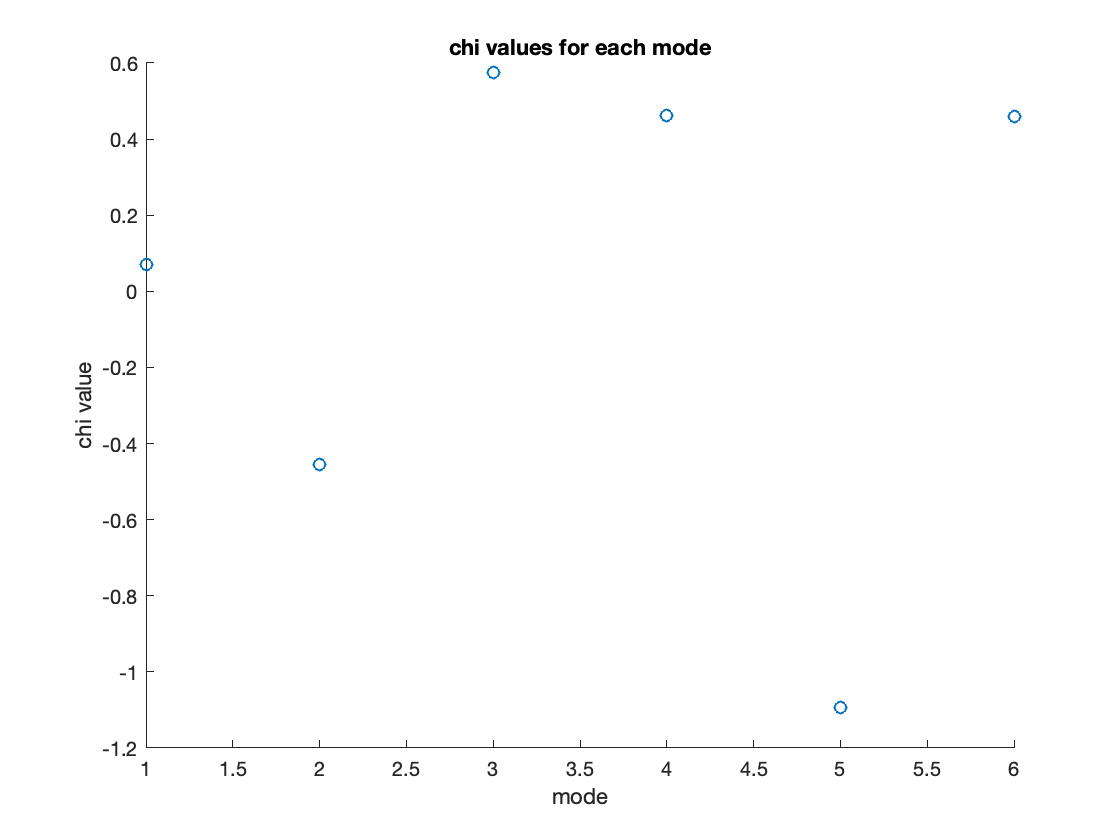

scatter(n,chi)
title('chi values for each mode')
xlabel('mode')
ylabel('chi value')

There is one frequency with a chi value magnitude of greater than one (-1.09). Since the gaussian distribution tells us we should expect around 1/3 of our values to have a chi magnitude of greater than one, our data appears consistant with that assumption. 